clc; clear;
syms l1 l2 l3 d1 d2 d3 theta1 theta2 theta3

DH =    [l1 d1 0 0;
        l2 0 0 theta2;
        l3 0 0 theta3];
q = [0, pi/4, pi/4];
l = [1245 685 685];

bot1 = manipulator(DH,l);
T = bot1.fkine()

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & l_{1}+l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T = bot1.fkine(q)

$$T = \left(\begin{array}{cccc} 0 & -1 & 0 & \frac{685\,\sqrt{2}}{2}+1245\\ 1 & 0 & 0 & \frac{685\,\sqrt{2}}{2}+685\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


J = bot1.Jacobian() %Validate this result

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$J = \left(\begin{array}{ccc} 0 & -l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)-l_{2}\,\sin\left(\theta_{2}\right) & -l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\\ 0 & l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right) & l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)\\ 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 1 & 1 \end{array}\right)$$

%bot1.currentProperties
[a, b, c] = bot1.ikine([10 10 20]);
%T1 = bot1.fkine([d1 theta2 theta3])
simplify(subs(T,{d1,theta2,theta3}, {a,b,c}))

$$ans = \left(\begin{array}{cccc} 0 & -1 & 0 & \frac{685\,\sqrt{2}}{2}+1245\\ 1 & 0 & 0 & \frac{685\,\sqrt{2}}{2}+685\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%Testing to figure out what's wrong with ikine
y = T(2,4);
x = T(1,4);
D = (y^2 + (x-l(1,1))^2 - l(1,2)^2 - l(1,3)^2)/(2*l(1,2)*l(1,3))

$$D = \frac{{\left(\frac{685\,\sqrt{2}}{2}+685\right)}^{2}}{938450}-\frac{3}{4}$$

theta3_plus = simplify(atan2(D,sqrt(1-D^2)))

$$theta3\_plus = \frac{\pi }{4}$$

theta3_minus = simplify(atan2(D,-sqrt(1-D^2)))

$$theta3\_minus = \frac{3\,\pi }{4}$$

theta2 = simplify(atan2(y,x-l(1,1)) - atan2(l(1,2) + l(1,3)*cos(theta3_minus),l(1,3)*sin(theta3_minus)))

$$theta2 = \frac{\pi }{4}$$

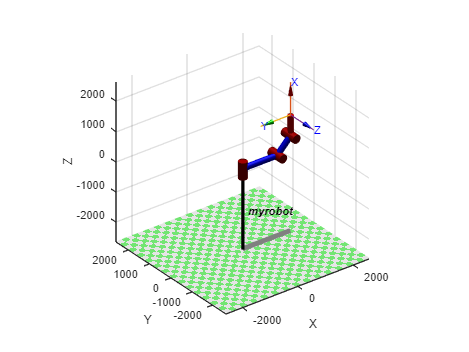


%Using robotics toolbox to confirm results
L1 = Link('a', l(1,1), 'd', 40, 'alpha', pi/2,'qlim',[0 40]);
L2 = Link('a', l(1,2),'d',0, 'alpha', 0);
L3 = Link('a', l(1,3),'d',0, 'alpha', 0);

bot = SerialLink([L1 L2 L3], 'name', 'myrobot');
%T1 = bot.fkine(q)
%bot.base = trotz(pi/2);
bot.plot(q)